# Integración numérica

### Problema

En dinámica de fluidos se puede analizar la velocidad que toma un determinado líquido dentro de una tubería circular. Si se asume que: 

- El flujo es más rápido en el centro de la tubería.

- En las paredes de la tubería la velocidad es nula.

Entonces se tiene que la velocidad del fluido con respecto al centro de la tubería viene dado por:


$$v\left(r\right)=v_{\max } \cdot {\left(1-\frac{r}{r_0 }\right)}^{\frac{1}{n}}$$


donde $r_0$ corresponde al radio de la tubería, $r$ la distancia desde el centro de la misma, $n$ es un número entero entre 1 y 5 y $v_{\max }$ la velocidad máxima del flujo en la tubería; tanto $n$ como $v_{\max }$ se pueden medir de manera experimental.

De esta manera, la velocidad promedio del líquido viene dado por:


$$v_{\mathrm{prom}} =\frac{\int_0^{r_o } v\left(r\right)\cdot \;2\pi r\;\mathrm{dr}\;}{\pi \;r_0^2 }$$


Sin embargo si se hace el cambio de variable$x=\frac{r}{r_0 }$, se puede calcular la velocidad promedio de un fluido en una tubería sin imporytar el radio que esta tenga.

Si se considera $n=8$ y que la velocidad máxima es aproximadamente $1\ldotp 5m/s$, calcule la velocidad promedio de un fluido en la tubería.

Solución:

Si se considera el cambio de variable $x=\frac{r}{r_0 }$ se tiene que:


$$x=\frac{r}{r_0 }\Rightarrow \mathrm{dx}=\frac{\mathrm{dr}}{r_0 }\Rightarrow r_0 \;\mathrm{dx}=\mathrm{dr}$$


Además, al cambiar los límites de integración se tiene que:


$$r\to 0\;\mathrm{entonces}\;x\to 0$$



$$r\to r_0 \;\mathrm{entonces}\;x\to 1$$


De esta manera, se obtiene la siguiente expresión:


$$v_{\mathrm{prom}} =\frac{\int_0^1 v_{\max } \cdot \;{\left(1-x\right)}^{\frac{1}{n}} \cdot 2\pi x\;r_0 \;r_0 \;\mathrm{dx}}{\pi r_0^2 \;}$$



$$=\frac{\int_0^1 v_{\max } \cdot \;{\left(1-x\right)}^{\frac{1}{n}} \cdot 2\pi x\;r_0^2 \;\mathrm{dx}}{\pi r_0^2 \;}$$



$$=\int_0^1 2\cdot \;v_{\max } \cdot \;{\left(1-x\right)}^{\frac{1}{n}} \;\mathrm{dx}$$



$$=2\cdot \;v_{\max } \int_0^1 {\left(1-x\right)}^{\frac{1}{n}} \;\mathrm{dx}$$


Para este caso particular, si se considera $n=8$ y $v_{\max } \approx 1\ldotp 5m/s$ se tiene:


$$\int_0^1 3{x\left(1-x\right)}^{\frac{1}{8}} \;\mathrm{dx}$$


La siguiente corresponde a la gráfica de la función $3{x\left(1-x\right)}^{\frac{1}{8}}$ en el intervalo $\left\lbrack 0,1\right\rbrack$:

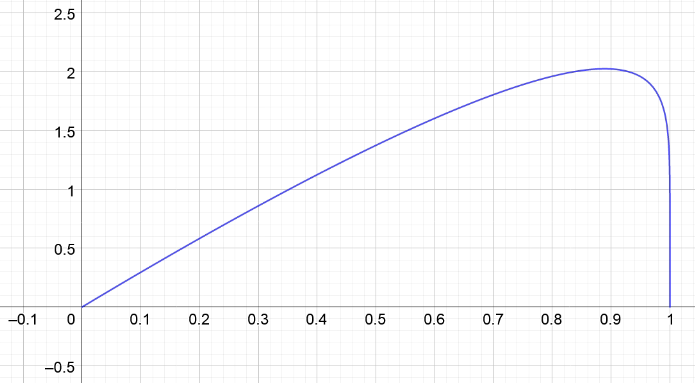

Como se quiere calcular la integral en el intervalo $\left\lbrack 0,1\right\rbrack$, se debe considerar como valor inicial $a=0$ y como valor final $b=1$. Para los métodos compuestos se tomará $n=100$.

Para dar solución a este problema se hará uso de "**Toolbox en Matlab para métodos numéricos**" creado en este proyecto.

Como primer paso, se debe ingresar la función en el recuadro llamado "$f\left(x\right)$" como se muestra en la siguiente imagen:

**NOTA: ** Tenga en cuenta que al ingresar la función se debe escribir en función de la variable independiente $x$.

Como segundo paso, se deben indicar los valores inicial y final. Como se mencionó anteriormente, se considerará $a=0$ y $b=1$. Estos valores se deben ingresar en los espacios llamados $\textrm{"a"}$ y $\textrm{"b"}$ como se muestra en la siguiente imagen:

Finalmente, se debe indicar (para los métodos compuestos) la cantidad $n$ de subintervalos que se desea generar. En este caso se considerará una cantidad de 100 subintervalos. Este valor se debe ingresar en el espacio llamado $\textrm{"n"}$ como se muestra en la siguiente imagen:

    *Esta casilla aparecerá bloqueada para los métodos simples.

A partir de este momento, solo se debe seleccionar el método con el cuál se desea aproximar integral de la función ingresada. Puede aproximar dicho valor por medio de los siguientes métodos:

- Rectángulo simple (Punto medio)

- Rectángulo compuesto (Punto medio)

- Trapecio simple

- Trapecio compuesto

- Simpson 1/3 simple

- Simpson 1/3 compuesto

- Simpson 3/8 simple

- Simpson 3/8 compuesto

A continuación se muestra el cómo se visualiza la lista desplegable de estas opciones:

Por defecto aparece seleccionado el método de Punto medio compuesto, sin embargo al hacer clic sobre la pestaña, se despliegan las demás opciones:

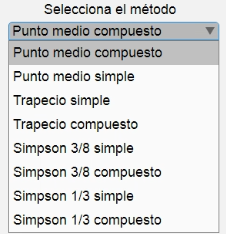

Para calcular dicho resultado, solo debe hacer clic sobre el botón llamado "Calcular":

 

A continuación se muestran y analizan los resultados obtenidos con cada uno de los métodos:

#### Método del Rectángulo simple (Punto medio)

- Al seleccionar el método "**Punto medio simple**" y dar clic en el botón "Calcular" la pantalla se visualiza de la siguiente manera:

#### 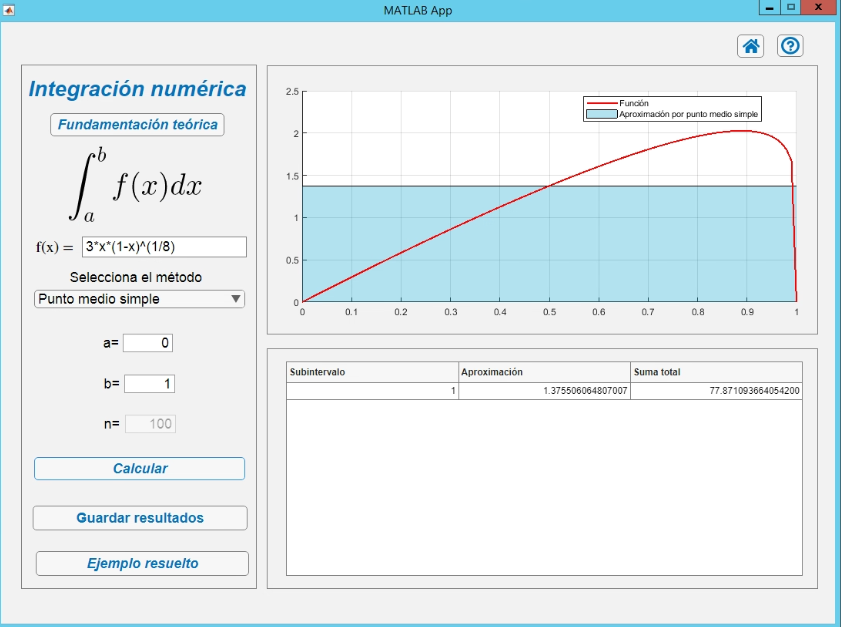

A continuación se muestra el gráfico que brindan la información:

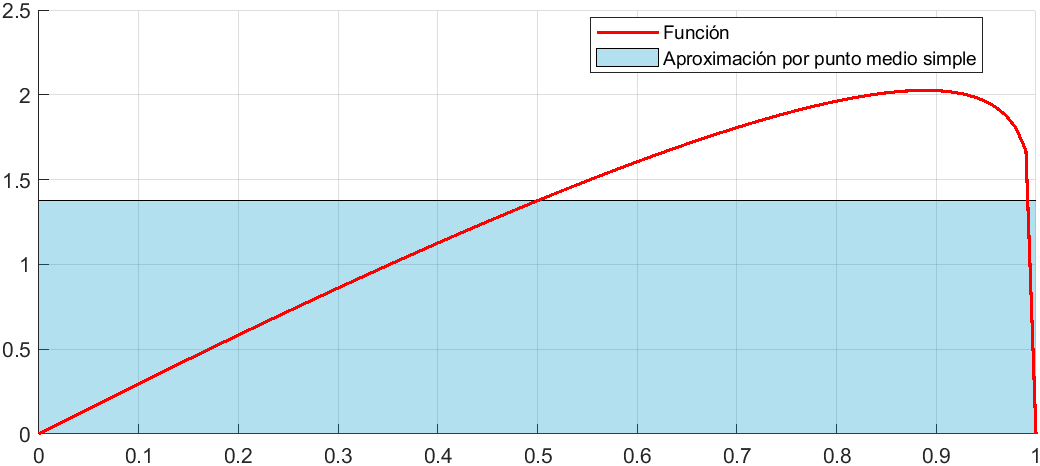

A partir de la información representada en este gráfico, es posible observar que el método empleado aproxima la integral con un solo rectángulo, el cual pasa por el punto medio de la función en el intervalo dado.

A continuación se muestra la tabla de datos generada:

format longG
Iteracion=1;
Aproximacion=1.37550606480701;
Suma=1.37550606480701;
T3=table(Iteracion, Aproximacion, Suma)

T3 = 1×3 table
    Iteracion      Aproximacion            Suma      
    _________    ________________    ________________

        1        1.37550606480701    1.37550606480701


#### Método del Rectángulo compuesto (Punto medio)

- Al seleccionar el método "**Punto medio compuesto**" y dar clic en el botón "Calcular" la pantalla se visualiza de la siguiente manera:

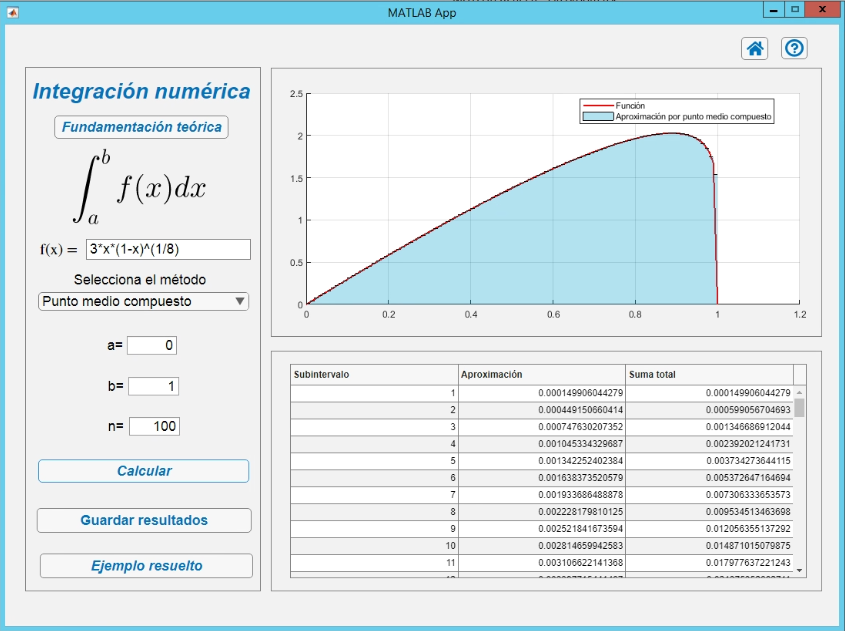

A continuación se muestra el gráfico que brindan la información:

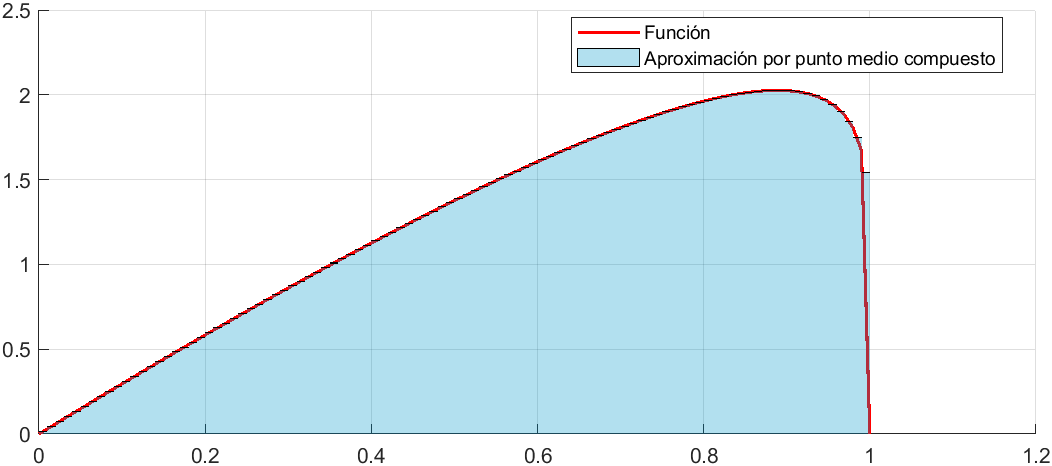

A partir de la información representada en este gráfico, es posible observar que el método empleado aproxima la integral con 100 rectángulos, cada uno pasando por el punto medio de la función en el subintervalo dado.

A continuación se muestra la tabla de datos generada:

format longG
Iteracion=[1
2
3
4
5
6
7
8
9
10
11
12
13
14
15
16
17
18
19
20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100];
Aproximacion=[0.000149906044278694
0.000449150660413979
0.000747630207351561
0.00104533432968699
0.00134225240238418
0.00163837352057896
0.00193368648887838
0.00222817981012513
0.00252184167359374
0.00281465994258329
0.0031066221413684
0.00339771544146741
0.00368792664718363
0.00397724218037208
0.00426564806438048
0.00455312990710904
0.00483967288312932
0.00512526171479759
0.00540988065229267
0.00569351345250266
0.00597614335667833
0.00625775306676417
0.00653832472031035
0.00681783986386027
0.0070962794246993
0.00737362368083965
0.00764985222910548
0.00792494395116916
0.00819887697737629
0.0084716286481811
0.00874317547299718
0.00901349308624893
0.00928255620038836
0.00955033855561777
0.00981681286603234
0.0100819507618674
0.0103457227275014
0.0106080980348282
0.0108690446715709
0.0111285292640615
0.0113865169939563
0.0116429715082988
0.0118978548222705
0.0121511272138929
0.0124027471098559
0.0126526709615454
0.0129008531102258
0.0131472456402035
0.0133917982186393
0.0136344579205059
0.0138751690369801
0.0141138728653237
0.0143505074780333
0.0145850074687178
0.0148173036717892
0.0150473228526137
0.0152749873642521
0.0155002147663097
0.0157229174006913
0.0159430019181976
0.0161603687488689
0.0163749115077484
0.0165865163262515
0.0167950610975247
0.0170004146219871
0.0172024356365697
0.0174009717078728
0.017595857965389
0.0177869156458744
0.0179739504136091
0.018156750413296
0.0183350840022067
0.0185086970952098
0.0186773100395947
0.0188406139148574
0.0189982661240693
0.0191498851056138
0.0192950439433816
0.0194332625848046
0.0195639982818265
0.0196866337387483
0.019800462265748
0.0199046689712586
0.0199983066385247
0.0200802643540526
0.0201492260766138
0.0202036149646889
0.0202415170834792
0.0202605744812561
0.0202578314052629
0.0202295063288343
0.020170641682006
0.0200745419876536
0.0199318236108271
0.0197286968453752
0.0194435781733357
0.0190395672727309
0.0184445630590801
0.0174811054507458
0.0153927276754896];
Suma=[0.000149906044278694
0.000599056704692673
0.00134668691204423
0.00239202124173122
0.0037342736441154
0.00537264716469436
0.00730633365357274
0.00953451346369788
0.0120563551372916
0.0148710150798749
0.0179776372212433
0.0213753526627107
0.0250632793098943
0.0290405214902664
0.0333061695546469
0.0378592994617559
0.0426989723448853
0.0478242340596828
0.0532341147119755
0.0589276281644782
0.0649037715211565
0.0711615245879207
0.077699849308231
0.0845176891720913
0.0916139685967906
0.0989875922776303
0.106637444506736
0.114562388457905
0.122761265435281
0.131232894083462
0.139976069556459
0.148989562642708
0.158272118843097
0.167822457398715
0.177639270264747
0.187721221026614
0.198066943754116
0.208675041788944
0.219544086460515
0.230672615724576
0.242059132718533
0.253702104226831
0.265599959049102
0.277751086262995
0.290153833372851
0.302806504334396
0.315707357444622
0.328854603084826
0.342246401303465
0.355880859223971
0.369756028260951
0.383869901126275
0.398220408604308
0.412805416073026
0.427622719744815
0.442670042597428
0.457945029961681
0.47344524472799
0.489168162128681
0.505111164046879
0.521271532795748
0.537646444303496
0.554232960629748
0.571028021727273
0.58802843634926
0.605230871985829
0.622631843693702
0.640227701659091
0.658014617304966
0.675988567718575
0.694145318131871
0.712480402134077
0.730989099229287
0.749666409268882
0.76850702318374
0.787505289307809
0.806655174413423
0.825950218356804
0.845383480941609
0.864947479223435
0.884634112962184
0.904434575227932
0.92433924419919
0.944337550837715
0.964417815191768
0.984567041268381
1.00477065623307
1.02501217331655
1.04527274779781
1.06553057920307
1.0857600855319
1.10593072721391
1.12600526920156
1.14593709281239
1.16566578965776
1.1851093678311
1.20414893510383
1.22259349816291
1.24007460361366
1.25546733128915];
T5=table(Iteracion, Aproximacion, Suma)

T5 = 100×3 table
    Iteracion        Aproximacion                Suma        
    _________    ____________________    ____________________

        1        0.000149906044278694    0.000149906044278694
        2        0.000449150660413979    0.000599056704692673
        3        0.000747630207351561     0.00134668691204423
        4         0.00104533432968699     0.00239202124173122
        5         0.00134225240238418      0.0037342736441154
        6         0.00163837352057896     0.00537264716469436
        7         0.00193368648887838     0.00730633365357274
        8         0.00222817981012513     0.00953451346369788
        9         0.00252184167359374      0.0120563551372916
       10         0.00281465994258329      0.0148710150798749
       11          0.0031066221413684      0.0179776372212433
       12         0.00339771544146741      0.0213753526627107
       13   

#### Método del Trapecio simple

- Al seleccionar el método "**Trapecio simple**" y dar clic en el botón "Calcular" la pantalla se visualiza de la siguiente manera:

#### 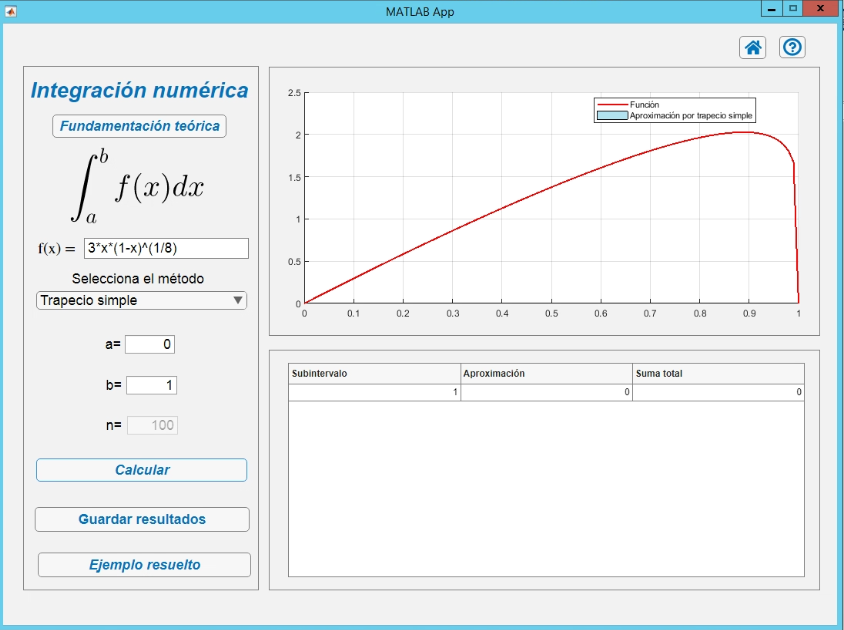

A continuación se muestra el gráfico que brindan la información:

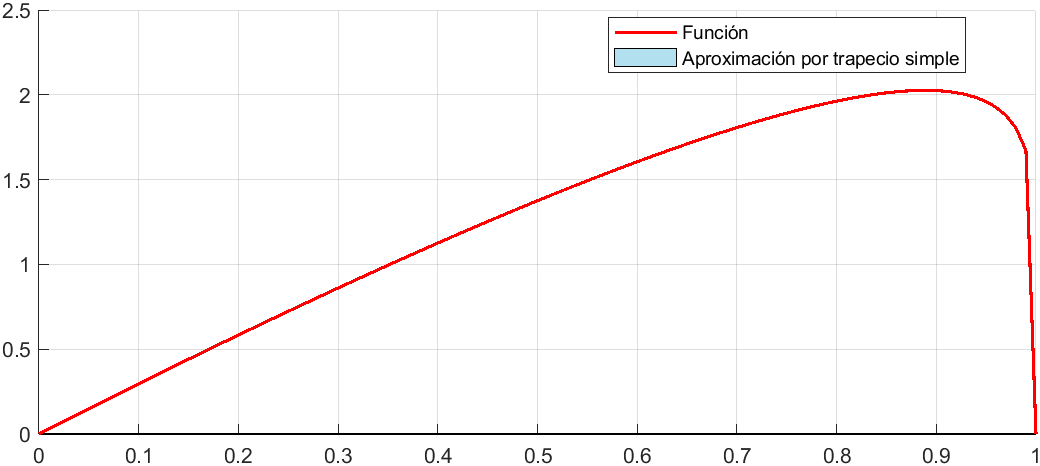

A partir de la información representada en este gráfico, es posible observar que el método empleado no es factible ya que al generar un trapecio con el punto inicial $\left(0,0\right)$ y el punto final $\left(1,0\right)$ la altura es cero. De esta manera la aproximación que se realiza es cero.

A continuación se muestra la tabla de datos generada:

format longG
Iteracion=1;
Aproximacion=0;
Suma=0;
T4=table(Iteracion, Aproximacion, Suma)

T4 = 1×3 table
    Iteracion    Aproximacion    Suma
    _________    ____________    ____

        1             0           0  


#### Método del Trapecio compuesto

- Al seleccionar el método "**Trapecio compuesto**" y dar clic en el botón "Calcular" la pantalla se visualiza de la siguiente manera:

#### 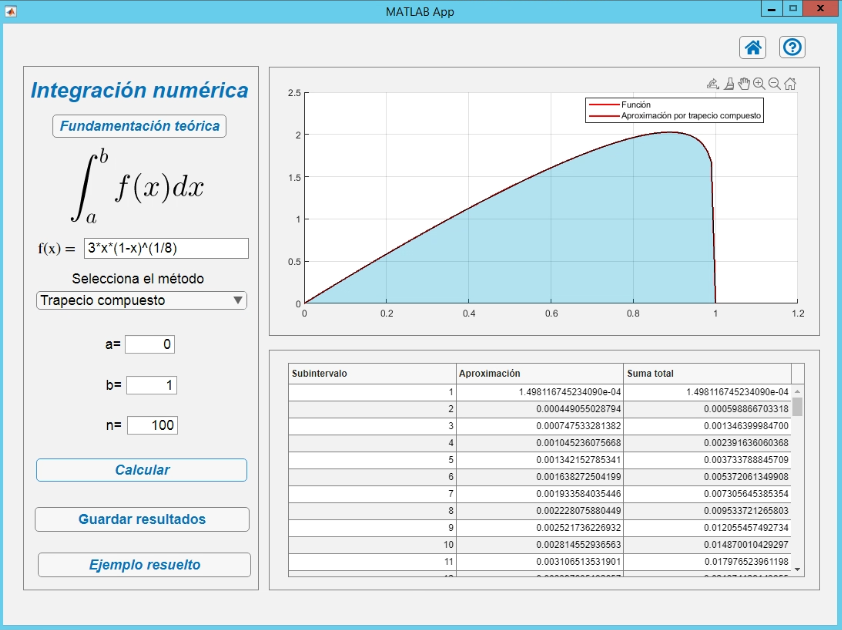

A continuación se muestra el gráfico que brindan la información:

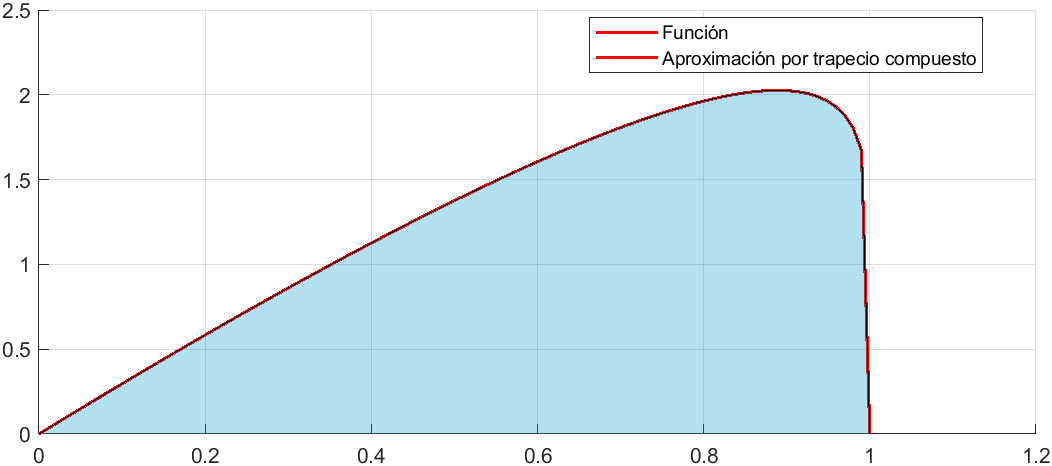

A partir de la información representada en este gráfico, es posible observar que el método empleado aproxima la integral con 100 trapecios, cada uno tomando como valores para la base los respectivos extremos del subintervalo dado y como altura, la imagen en la función de cada uno de estos extremos.

A continuación se muestra la tabla de datos generada:

format longG
Iteracion=[1
2
3
4
5
6
7
8
9
10
11
12
13
14
15
16
17
18
19
20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100];
Aproximacion=[0.000149811674523409
0.00044905502879438
0.000747533281382325
0.00104523607566787
0.00134215278534061
0.00163827250419902
0.00193358403544596
0.00222807588044892
0.00252173622693182
0.00281455293656293
0.00310651353190075
0.00339760518265663
0.00368781469123014
0.00397712847746934
0.0042655325626049
0.00455301255230239
0.00483955361877308
0.00512514048187857
0.00540975738915916
0.00569338809471032
0.00597601583682495
0.00625762331431236
0.00653819266139705
0.006817705421092
0.00709614251693175
0.0073734842229403
0.00764971013169762
0.0079247991203556
0.00819872931444077
0.00847147804926541
0.00874302182875134
0.0090133362814521
0.00928239611353727
0.00955017505847943
0.00981664582315739
0.0100817800300599
0.0103455481552402
0.0106079194616351
0.0108688619273195
0.0111283421682191
0.0113863253547533
0.0116427751218154
0.0118976534714308
0.012150920667357
0.0124025351207953
0.0126524532662887
0.0129006294267575
0.0131470156664961
0.0133915616307986
0.0136342143707016
0.0138749181511346
0.0141136142405227
0.0143502406796201
0.014584732027023
0.0148170190784426
0.0150470285563723
0.0152746827662699
0.0154998992147572
0.0157225901846187
0.015942662260513
0.0161600157982771
0.0163745443294657
0.0165861338912716
0.0167946622701621
0.016999998145365
0.0172020001156412
0.0174005155894688
0.0175953795146605
0.017786412918341
0.0179734212218169
0.0181561922868243
0.0183344941394077
0.018508072304601
0.0186766466682001
0.0188399077599473
0.0189975123235974
0.0191490780010545
0.0192941769064352
0.0194323277962732
0.0195629864463947
0.0196855337127282
0.0197992605649035
0.0199033491107359
0.0199968482335302
0.0200786418728228
0.0201474070768253
0.0202015575432279
0.0202391660941445
0.0202578557596635
0.0202546426482678
0.0202257021073079
0.0201660076186793
0.0200687476295293
0.0199243300288861
0.0197185580492707
0.0194289587042148
0.0190163488431772
0.018401080635221
0.0173653608627811
0.00835076867907669];
Suma=[0.000149811674523409
0.000598866703317789
0.00134639998470011
0.00239163606036799
0.0037337888457086
0.00537206134990762
0.00730564538535358
0.0095337212658025
0.0120554574927343
0.0148700104292973
0.017976523961198
0.0213741291438546
0.0250619438350848
0.0290390723125541
0.033304604875159
0.0378576174274614
0.0426971710462345
0.0478223115281131
0.0532320689172722
0.0589254570119825
0.0649014728488075
0.0711590961631198
0.0776972888245169
0.0845149942456089
0.0916111367625406
0.0989846209854809
0.106634331117179
0.114559130237534
0.122757859551975
0.13122933760124
0.139972359429992
0.148985695711444
0.158268091824981
0.16781826688346
0.177634912706618
0.187716692736678
0.198062240891918
0.208670160353553
0.219539022280873
0.230667364449092
0.242053689803845
0.25369646492566
0.265594118397091
0.277745039064448
0.290147574185243
0.302800027451532
0.31570065687829
0.328847672544786
0.342239234175584
0.355873448546286
0.369748366697421
0.383861980937943
0.398212221617563
0.412796953644586
0.427613972723029
0.442661001279401
0.457935684045671
0.473435583260428
0.489158173445047
0.50510083570556
0.521260851503837
0.537635395833303
0.554221529724575
0.571016191994737
0.588016190140102
0.605218190255743
0.622618705845212
0.640214085359872
0.658000498278213
0.67597391950003
0.694130111786854
0.712464605926262
0.730972678230863
0.749649324899063
0.76848923265901
0.787486744982608
0.806635822983662
0.825929999890097
0.845362327686371
0.864925314132765
0.884610847845494
0.904410108410397
0.924313457521133
0.944310305754663
0.964388947627486
0.984536354704311
1.00473791224754
1.02497707834168
1.04523493410135
1.06548957674962
1.08571527885692
1.1058812864756
1.12595003410513
1.14587436413402
1.16559292218329
1.1850218808875
1.20403822973068
1.2224393103659
1.23980467122868
1.24815543990776];
T=table(Iteracion, Aproximacion, Suma)

T = 100×3 table
    Iteracion        Aproximacion                Suma        
    _________    ____________________    ____________________

        1        0.000149811674523409    0.000149811674523409
        2         0.00044905502879438    0.000598866703317789
        3        0.000747533281382325     0.00134639998470011
        4         0.00104523607566787     0.00239163606036799
        5         0.00134215278534061      0.0037337888457086
        6         0.00163827250419902     0.00537206134990762
        7         0.00193358403544596     0.00730564538535358
        8         0.00222807588044892      0.0095337212658025
        9         0.00252173622693182      0.0120554574927343
       10         0.00281455293656293      0.0148700104292973
       11         0.00310651353190075       0.017976523961198
       12         0.00339760518265663      0.0213741291438546
       13    

#### Método de Simpson 1/3 simple

- Al seleccionar el método "**Simpson 1/3 simple**" y dar clic en el botón "Calcular" la pantalla se visualiza de la siguiente manera:

#### 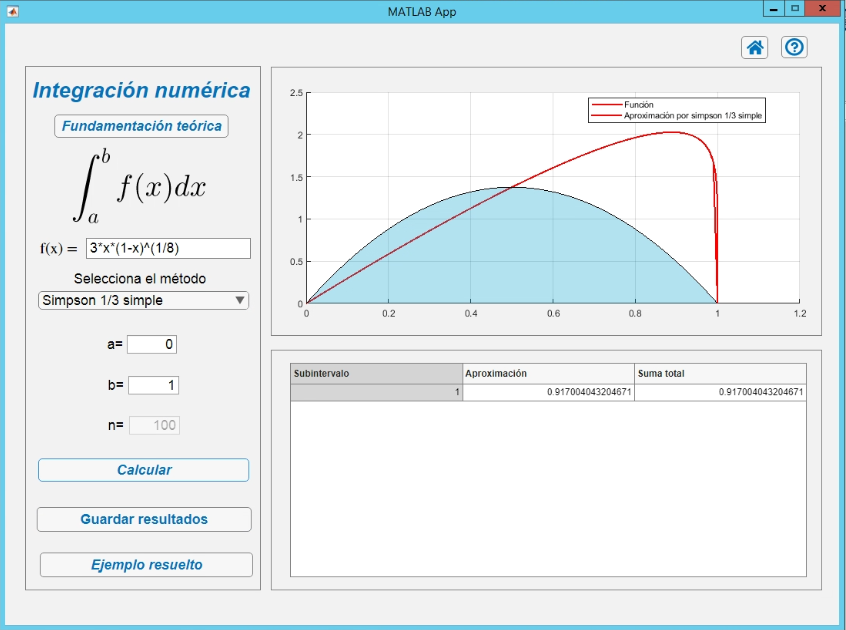

A continuación se muestra el gráfico que brindan la información:

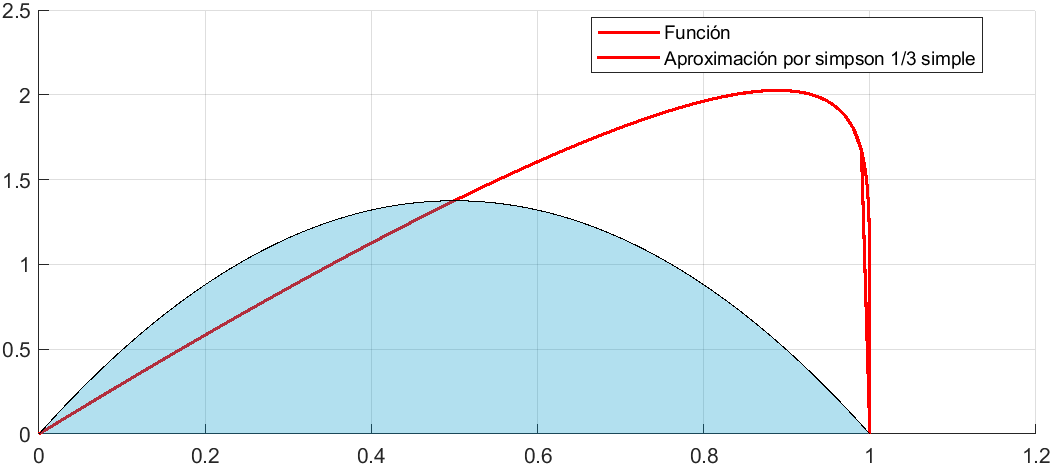

A partir de la información representada en este gráfico, es posible observar que el método empleado aproxima la integral por medio de una función cuadrática pasando por los puntos $\left(0,0,\right)$, $\left(\frac{1}{2},\sqrt[8]{\frac{6561}{512}}\right)$ y $\left(1,0\right)$.

A continuación se muestra la tabla de datos generada:

format longG
Iteracion=1;
Aproximacion=0.917004043204671;
Suma=0.917004043204671;
T6=table(Iteracion, Aproximacion, Suma)

T6 = 1×3 table
    Iteracion      Aproximacion             Suma       
    _________    _________________    _________________

        1        0.917004043204671    0.917004043204671


#### Método de Simpson 1/3 compuesto

- Al seleccionar el método "**Simpson 1/3 compuesto**" y dar clic en el botón "Calcular" la pantalla se visualiza de la siguiente manera:

#### 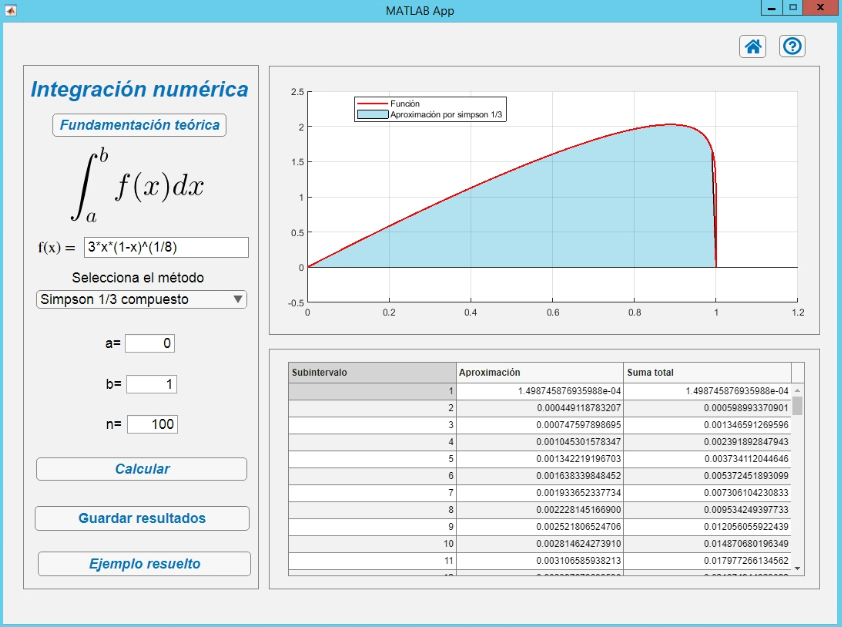

A continuación se muestra el gráfico que brindan la información:

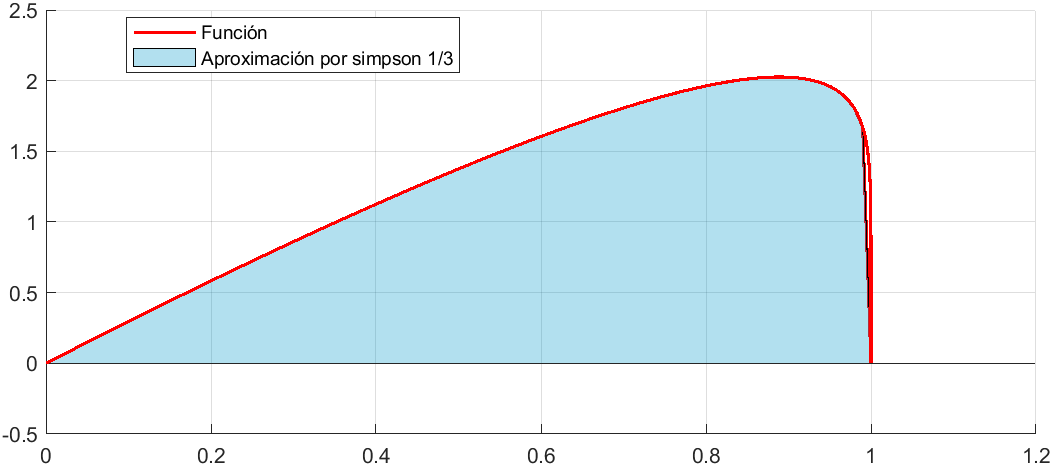

A partir de la información representada en este gráfico, es posible observar que el método empleado aproxima la integral generando una función cuadrática en cada uno de los 100 intervalos.

A continuación se muestra la tabla de datos generada:

format longG
Iteracion=[1
2
3
4
5
6
7
8
9
10
11
12
13
14
15
16
17
18
19
20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100];
Aproximacion=[0.000149874587693599
0.000449118783207446
0.000747597898695149
0.00104530157834728
0.00134221919670299
0.00163833984845231
0.00193365233773424
0.00222814516689973
0.00252180652470643
0.00281462427390984
0.00310658593821252
0.00339767868853049
0.00368788932853246
0.0039772042794045
0.00426560956378862
0.00455309078884016
0.00483963312834391
0.00512522130382458
0.0054098395645815
0.00569347166657188
0.00597610085006054
0.0062577098159469
0.00653828070067258
0.00681779504960419
0.00709623378877678
0.0073735771948732
0.00764980486330286
0.0079248956742313
0.00819882775639778
0.00847157844854254
0.00874312425824856
0.00901344081798332
0.00928250283810467
0.00955028405657165
0.00981675718507402
0.0100818938512649
0.0103456645367477
0.0106080385104305
0.0108689837568205
0.0111284668987807
0.011386453114222
0.0116429060461377
0.011897787705324
0.0121510583650476
0.0124026764468357
0.0126525983964598
0.0129007785490697
0.0131471689823011
0.0133917193560257
0.0136343767372378
0.0138750854083649
0.0141137866570567
0.0143504185452289
0.0145849156548195
0.0148172088073403
0.0150472247538666
0.0152748858315914
0.0155001095824588
0.0157228083286671
0.0159428886989694
0.0161602510986716
0.0163747891149875
0.0165863888479249
0.0167949281550705
0.0170002757964464
0.0172022904629269
0.0174008196684048
0.0175956984818128
0.0177867480700299
0.017973774016345
0.0181565643711388
0.0183348873812737
0.0185084888316736
0.0186770889157965
0.0188403785298874
0.0189980148572453
0.0191496160707607
0.0192947549310661
0.0194329509886275
0.0195636610033492
0.0196862670634083
0.0198000616987998
0.019904229017751
0.0199978205035265
0.020079723526976
0.0201486197433509
0.0202029291575352
0.0202407334203677
0.0202596682407252
0.0202567684862645
0.0202282382549921
0.0201690969942305
0.0200726105349455
0.0199293257501801
0.0197253172466737
0.019438705016962
0.019031827796213
0.0184300689177937
0.0174425239214242
0.0130454080100186];
Suma=[0.000149874587693599
0.000598993370901045
0.00134659126959619
0.00239189284794348
0.00373411204464647
0.00537245189309878
0.00730610423083302
0.00953424939773275
0.0120560559224392
0.014870680196349
0.0179772661345615
0.021374944823092
0.0250628341516245
0.029040038431029
0.0333056479948176
0.0378587387836578
0.0426983719120017
0.0478235932158263
0.0532334327804077
0.0589269044469796
0.0649030052970402
0.0711607151129871
0.0776989958136596
0.0845167908632638
0.0916130246520406
0.0989866018469138
0.106636406710217
0.114561302384448
0.122760130140846
0.131231708589388
0.139974832847637
0.14898827366562
0.158270776503725
0.167821060560296
0.17763781774537
0.187719711596635
0.198065376133383
0.208673414643814
0.219542398400634
0.230670865299415
0.242057318413637
0.253700224459774
0.265598012165098
0.277749070530146
0.290151746976982
0.302804345373441
0.315705123922511
0.328852292904812
0.342244012260838
0.355878388998076
0.369753474406441
0.383867261063497
0.398217679608726
0.412802595263546
0.427619804070886
0.442667028824753
0.457941914656344
0.473442024238803
0.48916483256747
0.505107721266439
0.521267972365111
0.537642761480098
0.554229150328023
0.571024078483094
0.58802435427954
0.605226644742467
0.622627464410872
0.640223162892685
0.658009910962715
0.67598368497906
0.694140249350198
0.712475136731472
0.730983625563146
0.749660714478942
0.76850109300883
0.787499107866075
0.806648723936836
0.825943478867902
0.845376429856529
0.864940090859879
0.884626357923287
0.904426419622087
0.924330648639838
0.944328469143364
0.96440819267034
0.984556812413691
1.00475974157123
1.02500047499159
1.04526014323232
1.06551691171858
1.08574514997358
1.10591424696781
1.12598685750275
1.14591618325293
1.16564150049961
1.18508020551657
1.20411203331278
1.22254210223057
1.239984626152
1.25303003416202];
T7=table(Iteracion, Aproximacion, Suma)

T7 = 100×3 table
    Iteracion        Aproximacion                Suma        
    _________    ____________________    ____________________

        1        0.000149874587693599    0.000149874587693599
        2        0.000449118783207446    0.000598993370901045
        3        0.000747597898695149     0.00134659126959619
        4         0.00104530157834728     0.00239189284794348
        5         0.00134221919670299     0.00373411204464647
        6         0.00163833984845231     0.00537245189309878
        7         0.00193365233773424     0.00730610423083302
        8         0.00222814516689973     0.00953424939773275
        9         0.00252180652470643      0.0120560559224392
       10         0.00281462427390984       0.014870680196349
       11         0.00310658593821252      0.0179772661345615
       12         0.00339767868853049       0.021374944823092
       13   

#### Método de Simpson 3/8 simple

- Al seleccionar el método "**Simpson 3/8 simple**" y dar clic en el botón "Calcular" la pantalla se visualiza de la siguiente manera:

#### 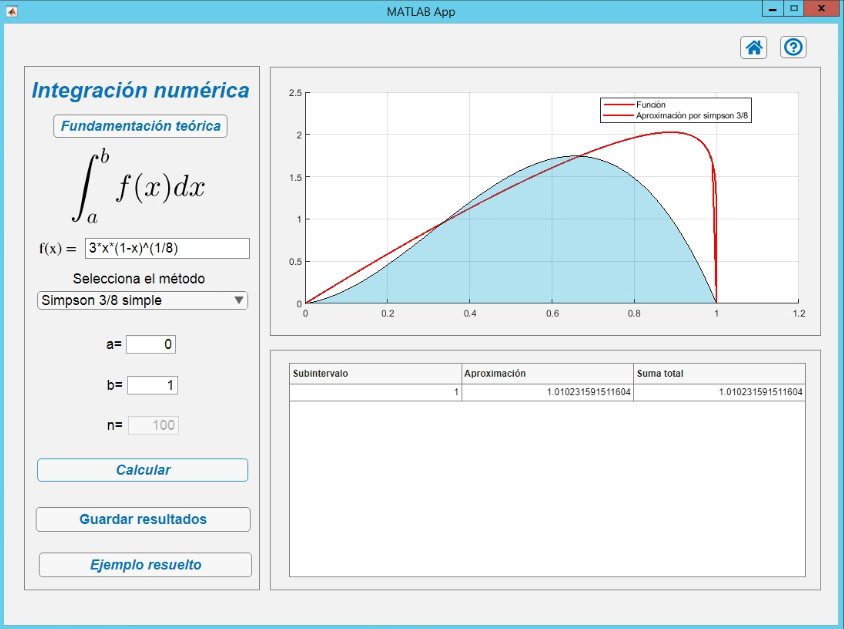

A continuación se muestra el gráfico que brindan la información:

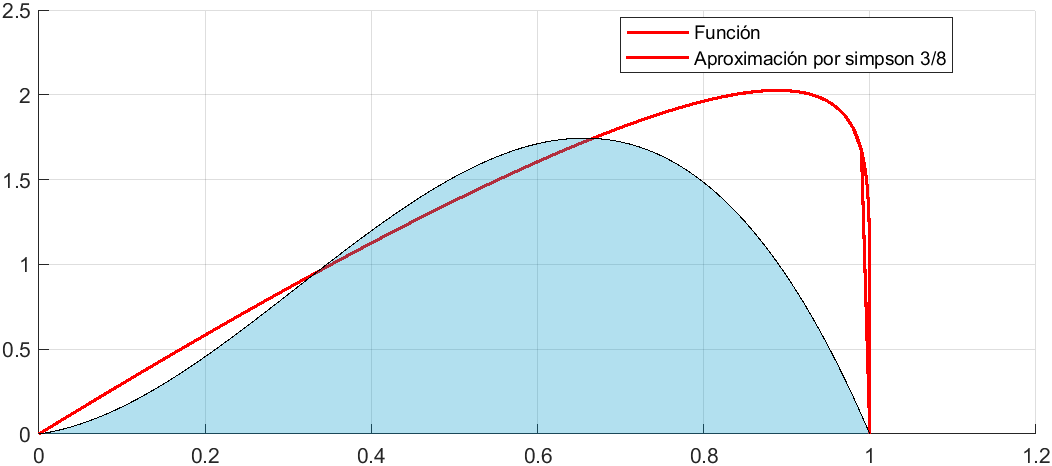

A partir de la información representada en este gráfico, es posible observar que el método empleado aproxima la integral por medio de una función cúbica pasando por los puntos $\left(0,0,\right)$, $\left(\frac{1}{3},\sqrt[8]{\frac{2}{3}}\right)$, $\left(\frac{1}{6},\sqrt[8]{\frac{256}{3}}\right)$ y $\left(1,0\right)$.

A continuación se muestra la tabla de datos generada:

format longG
Iteracion=1;
Aproximacion=1.0102315915116;
Suma=1.0102315915116;
T9=table(Iteracion, Aproximacion, Suma)

T9 = 1×3 table
    Iteracion     Aproximacion           Suma      
    _________    _______________    _______________

        1        1.0102315915116    1.0102315915116


#### Método de Simpson 3/8 compuesto

- Al seleccionar el método "**Simpson 3/8 compuesto**" y dar clic en el botón "Calcular" la pantalla se visualiza de la siguiente manera:

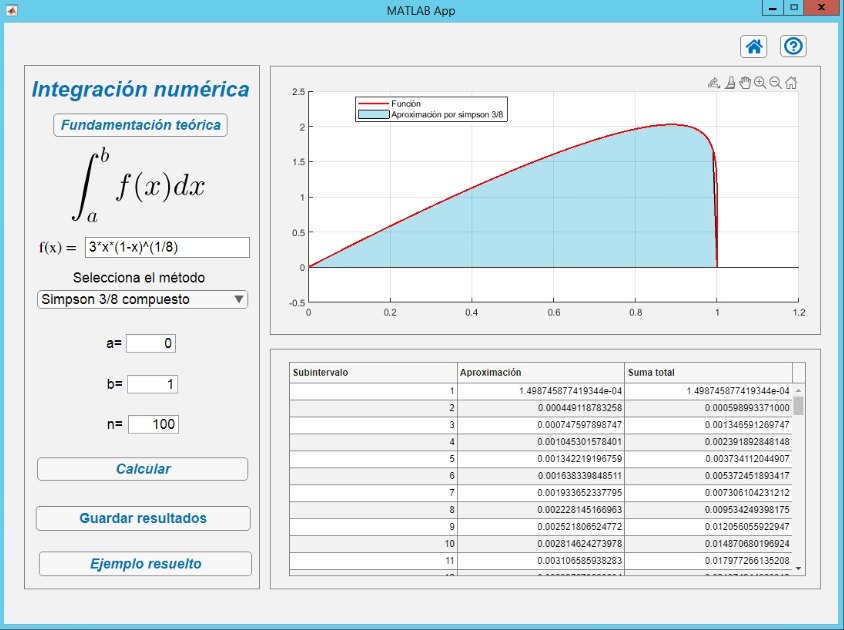

A continuación se muestra el gráfico que brindan la información:

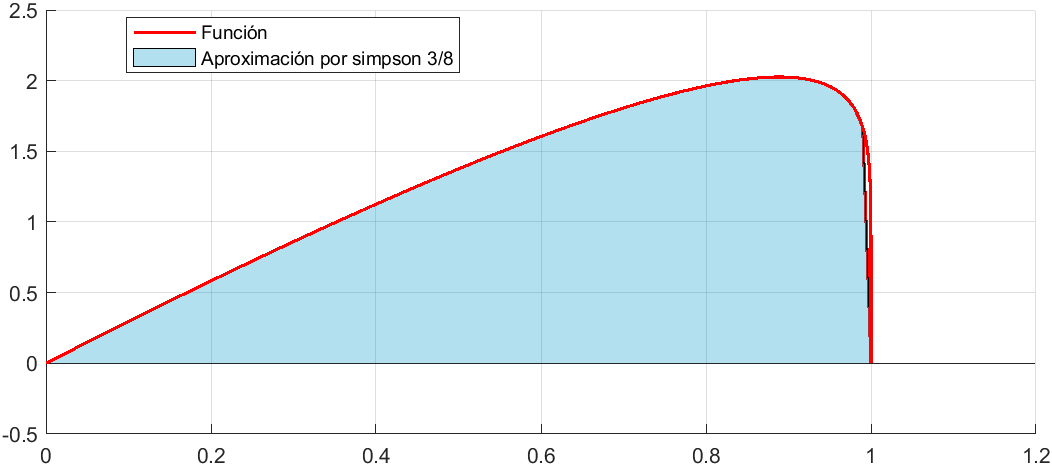

A partir de la información representada en este gráfico, es posible observar que el método empleado aproxima la integral generando una función cúbica en cada uno de los 100 intervalos.

A continuación se muestra la tabla de datos generada:

format longG
Iteracion=[1
2
3
4
5
6
7
8
9
10
11
12
13
14
15
16
17
18
19
20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100];
Aproximacion=[0.000149874587741934
0.00044911878325757
0.000747597898747147
0.00104530157840125
0.00134221919675902
0.0016383398485105
0.00193365233779471
0.00222814516696259
0.00252180652477181
0.00281462427397786
0.00310658593828333
0.00339767868860424
0.00368788932860931
0.00397720427948461
0.00426560956387218
0.00455309078892736
0.00483963312843496
0.0051252213039197
0.00540983956468093
0.00569347166667587
0.00597610085016936
0.00625770981606086
0.00653828070079198
0.00681779504972937
0.00709623378890812
0.00737357719501109
0.00764980486344772
0.0079248956743836
0.00819882775655801
0.00847157844871123
0.00874312425842631
0.00901344081817076
0.00928250283830249
0.0095502840567806
0.00981675718529492
0.0100818938514986
0.0103456645369952
0.0106080385106929
0.0108689837570989
0.0111284668990765
0.0113864531145365
0.0116429060464725
0.0118977877056808
0.0121510583654283
0.0124026764472424
0.0126525983968948
0.0129007785495355
0.0131471689828006
0.0133917193565622
0.0136343767378147
0.0138750854089863
0.014113786657727
0.0143504185459532
0.0145849156556034
0.0148172088081903
0.0150472247547899
0.0152748858325964
0.0155001095835549
0.0157228083298651
0.0159428887002818
0.0161602511001126
0.0163747891165736
0.0165863888496754
0.0167949281570077
0.0170002757985963
0.0172022904653203
0.017400819671078
0.0175956984848087
0.0177867480733998
0.0179737740201504
0.0181565643754538
0.0183348873861884
0.018508488837298
0.0186770889222663
0.0188403785373706
0.0189980148659525
0.0191496160809575
0.0192947549430915
0.0194329510029182
0.0195636610204751
0.019686267084122
0.0198000617241098
0.0199042290490297
0.0199978205426743
0.0200797235766764
0.0201486198074769
0.0202029292418173
0.0202407335335305
0.0202596683964975
0.0202567687071008
0.0202282385793439
0.0201690974916971
0.0200726113404169
0.0199293271486912
0.0197253199126298
0.0194387108130908
0.0190318431732435
0.0184301261338497
0.0174429588338629
0.013557489085916];
Suma=[0.000149874587741934
0.000598993370999504
0.00134659126974665
0.0023918928481479
0.00373411204490692
0.00537245189341742
0.00730610423121213
0.00953424939817472
0.0120560559229465
0.0148706801969244
0.0179772661352077
0.021374944823812
0.0250628341524213
0.0290400384319059
0.0333056479957781
0.0378587387847054
0.0426983719131404
0.0478235932170601
0.053233432781741
0.0589269044484169
0.0649030052985862
0.0711607151146471
0.0776989958154391
0.0845167908651685
0.0916130246540766
0.0989866018490877
0.106636406712535
0.114561302386919
0.122760130143477
0.131231708592188
0.139974832850615
0.148988273668785
0.158270776507088
0.167821060563868
0.177637817749163
0.187719711600662
0.198065376137657
0.20867341464835
0.219542398405449
0.230670865304526
0.242057318419062
0.253700224465535
0.265598012171215
0.277749070536644
0.290151746983886
0.302804345380781
0.315705123930316
0.328852292913117
0.342244012269679
0.355878389007494
0.36975347441648
0.383867261074207
0.39821767962016
0.412802595275764
0.427619804083954
0.442667028838744
0.45794191467134
0.473442024254895
0.48916483258476
0.505107721285042
0.521267972385155
0.537642761501729
0.554229150351404
0.571024078508412
0.588024354307008
0.605226644772328
0.622627464443406
0.640223162928215
0.658009911001615
0.675983685021765
0.694140249397219
0.712475136783407
0.730983625620705
0.749660714542972
0.768501093080342
0.787499107946295
0.806648724027252
0.825943478970344
0.845376429973262
0.864940090993737
0.884626358077859
0.904426419801969
0.924330648850998
0.944328469393673
0.964408192970349
0.984556812777826
1.00475974201964
1.02500047555317
1.04526014394967
1.06551691265677
1.08574515123612
1.10591424872781
1.12598686006823
1.14591618721692
1.16564150712955
1.18508021794264
1.20411206111588
1.22254218724973
1.2399851460836
1.25354263516951];
T8=table(Iteracion, Aproximacion, Suma)

T8 = 100×3 table
    Iteracion        Aproximacion                Suma        
    _________    ____________________    ____________________

        1        0.000149874587741934    0.000149874587741934
        2         0.00044911878325757    0.000598993370999504
        3        0.000747597898747147     0.00134659126974665
        4         0.00104530157840125      0.0023918928481479
        5         0.00134221919675902     0.00373411204490692
        6          0.0016383398485105     0.00537245189341742
        7         0.00193365233779471     0.00730610423121213
        8         0.00222814516696259     0.00953424939817472
        9         0.00252180652477181      0.0120560559229465
       10         0.00281462427397786      0.0148706801969244
       11         0.00310658593828333      0.0179772661352077
       12         0.00339767868860424       0.021374944823812
       13   

### Comparación de resultados

A continuación se brinda una tabla resumen de los datos obtenudos con cada uno de los métodos:

Metodo=["Punto medio simple";"Punto medio compuesto";"Trapecio simple";"Trapecio compuesto";"Simpson 1/3 simple"; "Simpson 1/3 compuesto"; "Simpson 3/8 simple"; "Simpson 3/8 compuesto"];
Subintervalo=[1;100;1;100;1;100;1;100];
Aproximacion=[1.37550606480701;1.25546733128915;0;1.24815543990776;0.917004043204671;1.25303003416202;1.0102315915116;1.25354263516951];
T11=table(Metodo,Subintervalo,Aproximacion)

T11 = 8×3 table
            Metodo             Subintervalo      Aproximacion   
    _______________________    ____________    _________________

    "Punto medio simple"             1          1.37550606480701
    "Punto medio compuesto"        100          1.25546733128915
    "Trapecio simple"                1                         0
    "Trapecio compuesto"           100          1.24815543990776
    "Simpson 1/3 simple"             1         0.917004043204671
    "Simpson 1/3 compuesto"        100          1.25303003416202
    "Simpson 3/8 simple"             1           1.0102315915116
    "Simpson 3/8 compuesto"        100          1.25354263516951


### Ejercicios propuestos

- Considere la función $f\left(x\right)=x^2 +1$. Aproxime $\int_0^3 f\left(x\right)\textrm{dx}$ usando: 1) Regla de rectángulo simple, 2) Regla de trapecio simple. Mejore las aproximaciones anteriores al realizar una partición del intervalo $\left\lbrack 0,3\right\rbrack$ en tres subintervalos igualmente espaciados.

- Aproxime el valor de la integral $\int_0^2 \frac{2x+1}{x^2 +x}\textrm{dx}$ por medio de Simpson $\frac{1}{3}$ simple y compuesto y compare los resultados. Además aproxime usando Simple $\frac{3}{8}$ y compuesto.

-  Aproxime el valor de la integral $\int_0^2 \frac{1}{\sqrt{x-1}}\textrm{dx}$ por medio de Simpson $\frac{1}{3}$ simple y compuesto,  compare los resultados. Además aproxime usando la Regla  Simpson simple $\frac{3}{8}$ y compuesto.

- Calcule el área de la región limitada por las siguientes funciones utilizando el método de Simpson $\frac{3}{8}$ con $n=10$ (Funciones: $y=x+1$, $y=0$ (EJE OX), $x=0$, $x=1$).

- Aproxime el valor de la integral definida $\int_0^1 \sin \left(e^{x^2 } \right)\textrm{dx}$ utilizando la fórmula de los trapecios con 5 subintervalos.

### Referencias

- Burden, A., Burden, R. y Faires, J. (2017). *Análisis Numérico* (10a ed.). México. Grupo Editorial Iberoamérica.

- Chapra, S.C. y Canale, R. (2007). M*étodos numéricos para Ingenieros* (5a ed.). México. Editorial MacGraw-Hill.

- Chavarría, J. (2014). *Métodos numéricos*. Editorial Tecnológica de Costa Rica.